clearvars; close all; clc;

# Theoretical reference

2024-06-16, JVsound, J.G. Vermond

## Introduction

This document describes the underlying theory used in the Matlab Audio Toolbox. It serves also as a recap how calculations including complex numbers are carried out.

## Complex numbers

Complex numbers and associated operations simplifies the solution of a differential equation in which the steady-state response for a sinusoidally time-varying excitation is to be determined, by reducing the differential equation to an algebraic equation involving phasors.

The concept of a complex number is defined by

$\sqrt{-1} = j$, or $j^2=-1$

A complex number in rectangular form has a real part and an imaginary part. The real and imaginary part can be considered as orthogonal axes. For example:


$$z = a + jb= 3 + j8$$


where $a=3$ is the real part and $b=8$ the imaginary part. This can be shown in the complex plane, see below.

% Define complex number:
z 					= 3 + 1i*8;

fig1 				= figure;
ax1 				= axes(fig1); hold on; grid on; axis equal;
ax1.FontSize 		= 8;
ax1.YLim 			= [-2 10];
ax1.XLabel.String 	= "Real";
ax1.YLabel.String 	= "Imag";

p1 	= plot(ax1,[real(z) real(z) 0],[0 imag(z) imag(z)],LineWidth=1,LineStyle="--");
plot(ax1,real(z),imag(z),Marker=".",Color=p1.Color,MarkerSize=15);

plot(ax1,ax1.XLim,[0 0],Color=[.4 .4 .4])
plot(ax1,[0 0],ax1.YLim,Color=[.4 .4 .4])

text(ax1,real(z) + .2,imag(z),"(3 + j8)","HorizontalAlignment","left","VerticalAlignment","bottom")

The complex number can also be expressed in exponential form:


$$z = Ae^{j\phi}$$


where $A$ is the magnitude and $\phi$ is the phase angle. This can be complemented by Euler's identy:


$$Ae^{j\phi} = A(\cos\phi + j\sin\phi)$$



$$Ae^{j\phi}=A\cos\phi + jA\sin\phi$$


Converting between rectangular and exponential form is done by:


$$a +jb = A\cos\phi +jA\sin\phi$$


- 
$$a = A\cos\phi$$


- 
$$b=A\sin\phi$$


The following hold:

- $a^2 + b^2 = A^2$ - Pythagoras

- 
$$\cos\phi = \frac{a}{A}$$


- 
$$\sin\phi=\frac{b}{A}$$


- 
$$\tan\phi = \frac{a}{b}$$


Thus:

- 
$$A = \sqrt{a^2 + b^2}$$


- 
$$\phi =atan2(b,a)$$


To go from the rectangular form to exponential and polar form:


$$z = 3 + j8 = \sqrt{3^2 + 8^2} e^{j\cdot atan2(8,3)} = 8.54e^{j1.212} = 8.54 \angle 69.44\degree$$


% Magnitude:
A 			= sqrt(3^2 + 8^2)

A = 8.5440


% Phase:
phi 		= atan2(8,3)

phi = 1.2120

phideg 		= phi * 180/pi

phideg = 69.4440

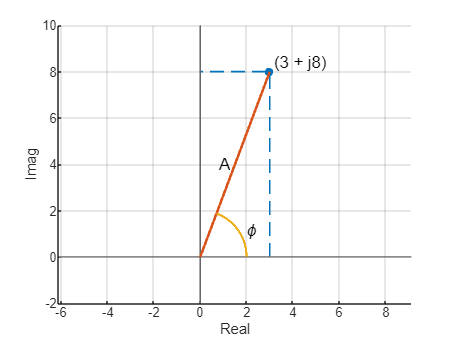


% Plot magnitude and angle (exponential form):
ax1.ColorOrderIndex 	= 2;
plot(ax1,[0 real(z)],[0 imag(z)],LineWidth=1.5)
text(ax1,real(z)/2-.2,imag(z)/2,"A",HorizontalAlignment="right")

phiarray 	= 0:.001:phi;
phireal 	= cos(phiarray) * 2;
phiimag 	= sin(phiarray) * 2;
plot(ax1,phireal,phiimag,LineWidth=1.5)
text(ax1,mean(phireal)+0.4,mean(phiimag),"\phi")

The phasor form is quite similar to the exponential form: only the frequency and phase is split:


$$A\cos(\omega t + \phi) = \Re[Ae^{jwt + \phi}] = \Re[Ae^{jwt}e^{j\phi}] = \Re[\bar{A}e^{jwt}]
$$


where $\bar{A} = e^{j\phi}$ is called the phasor. It contains the magnitude and the phase. Why use phasors and the complex plane?

- Addition, subtraction of harmonic signals is less complicated in exponential or phasor form.

- Linear first order differential equations can be solved with algebraic equations in phasor form.

### Example 1 - Addition of harmonic signals

Adding two harmonic signals and express this as one combined harmonic signal:


$$5\sin(\omega t) - 10\cos(\omega t + 30\degree)$$


- Convert to only cosine functions: $5\cos(\omega t - 90\degree) - 10 \cos(\omega t + 30\degree)$

- Phasor form: $\Re[5e^{-j}e^{jwt} - 10e^{j\pi/6}e^{jwt}]$

- Extract $e^{jwt}$: $\Re[(5e^{-j} - 10e^{j\pi/6})e^{jwt}]$

- Rectangular form: $\Re[(0 - j5 - (8.66 + j5))e^{jwt}]$

- Complex addition: $\Re[ (-8.66 -j10)e^{jwt}]$

- Back to cosine function: $\sqrt{(-8.66)^2+ (-10)^2} \cos(\omega t + atan2(-10,-8.66))$

- Result: $13.23\cos(\omega t -131\degree)$

See the following figure, for a frequency of 10Hz, that the single cosine function represents the combination of the sine and cosine functions perfectly.

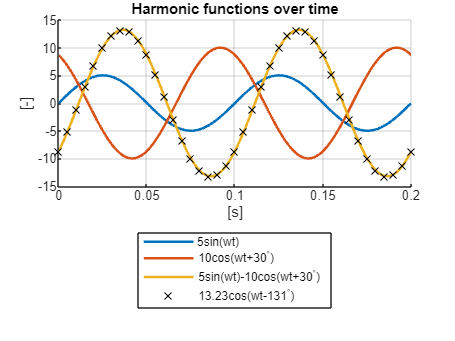

% Example 1

% Frequency
f 				= 10;
w 				= 2*pi*f;

% Time
t 				= 0:.001:1/f*2;

% Cosine functions 1 and 2:
c1 				= 5 * sin(w*t);
c2 				= 10 * cos(w*t + 30/180*pi);

% Combined into c3:
c3 				= c1 - c2;

% Result from single cosine function:
t2 				= t(1):0.005:t(end);
c4 				= 13.23 * cos(w*t2 -131/180*pi);

% Figure
fig2 				= figure;
ax2 				= axes(fig2); hold on; grid on;
ax2.FontSize 		= 8;
ax2.XLabel.String 	= "[s]";
ax2.YLabel.String 	= "[-]";
ax2.Title.String 	= "Harmonic functions over time";
ax2.XLim 			= [t(1) t(end)];

plot(ax2,t,c1,LineWidth=1.5)
plot(ax2,t,c2,LineWidth=1.5)
plot(ax2,t,c3,LineWidth=1.5)
plot(ax2,t2,c4,LineStyle="none",Marker="x",Color="k")

% Legend:
leg2 	= legend(ax2,"5sin(wt)","10cos(wt+30^\circ)","5sin(wt)-10cos(wt+30^\circ)","13.23cos(wt-131^\circ)");
leg2.Location = "southoutside";

### Example 2 - First order linear differential equation


$$R \cdot \Re[\bar{I}e^{j\omega t}] + L\frac{d}{dt}\Re[\bar{I}e^{j\omega t}] = \Re[\bar{V}e^{j\omega t}]$$


Nog vertellen waarom je rekenen met complex nummers alleen kan doen bij:

- lineaire operaties, so the complex numbers don't get mixed up: $j^2 = -1$

- Vermogen is geen lineaire berekening: $P = \frac{V^2}{Z}$, en heeft de dubbele frequentie van de current en voltage.

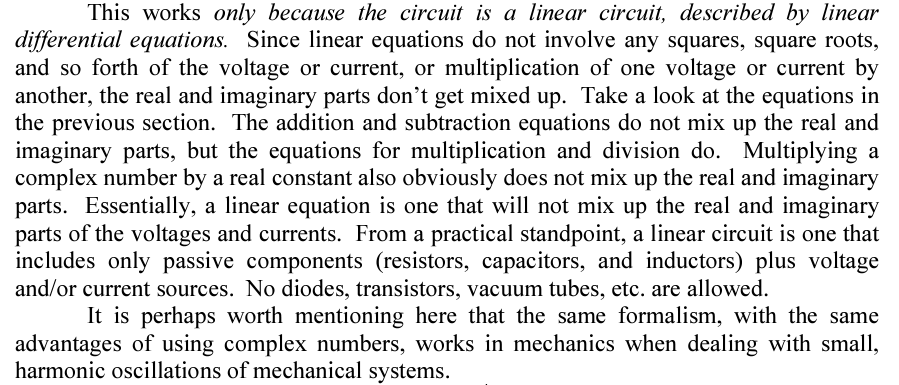

## 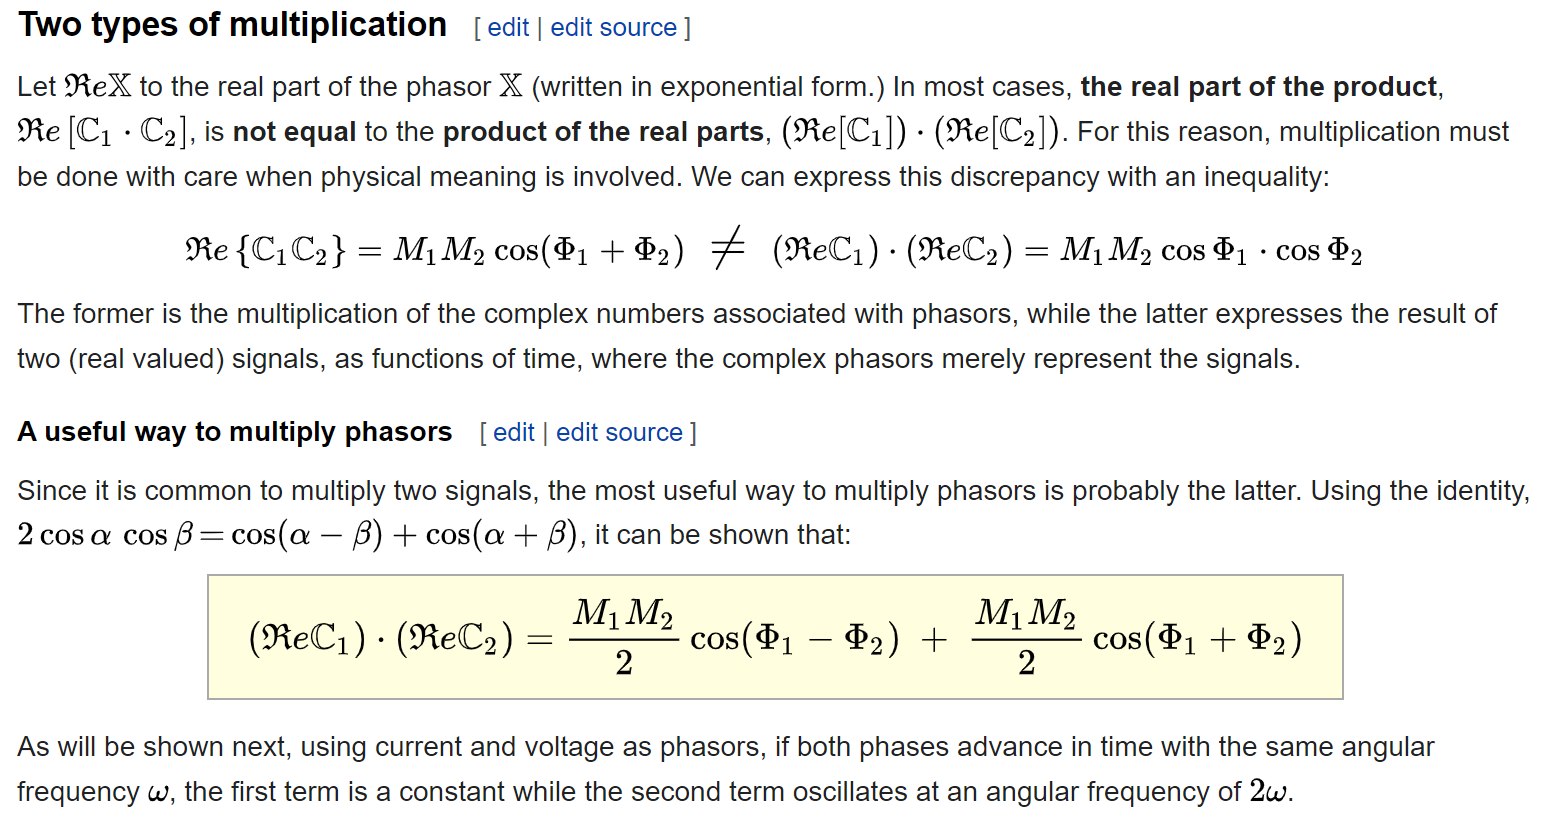

## Acoustic power

Sound power or acoustic power is the rate at which sound energy is emitted, reflected, transmitted or received, per unit time [Wikipedia]. For a sound source, unlike sound pressure, sound power is neither room-dependent nor distance-dependent.

For an equivalent acoustic circuit with a radiation resistance of $Z_r$, volume velocity $Q$ and pressure $p$, the instantenuous sound power is:


$$P(t) = \Re[Q(t)] \cdot \Re[p(t)] = \Re\left[\frac{p(t)}{Z_r}\right] \cdot \Re[p(t)]$$


### Acoustic power Hornresp

From the Hornresp Help:

"Constant directivity sound pressure produced at a point source normalised distance of one metre when the driver is supplied with a signal of a given voltage, versus frequency in hertz. The level is expressed in decibels relative to the standard reference sound pressure of 20 micropascals. The acoustical power output producing the constant directivity sound pressure is assumed to radiate uniformly into the solid angle specified by the Ang input parameter.

The Directivity Response tool can be used to take into account the frequency dependent directional characteristics of direct radiating single drivers and finite single-segment horns."

***Complex power in RL circuit***

Consider a circuit with a resistor with resistance $R$ of 10Ohm and an inductor with inductance of 1H. The source is a harmonic voltage with an magnitude $V_0$ of 25V:


$$V_S(t) = V_0\cos(wt+\phi)$$


The circular frequency is 2*pi*10 rad/s. The phase angle of the source, $\phi$ is 0deg. The impedance of the circuit, $Z$ is:


$$Z = R + j\omega L = 10 + j2\pi 10 L$$


The current becomes:


$$I(t) = \frac{V_s(t)}{Z} $$


In rectangular form:


$$I(t) =  \frac{V_0}{10+j2\pi 10} = 0.0618 - j0.388$$


Magnitude of $|I| = \sqrt{0.0618^2 + (-0.388)^2} =0.393A$

Average power:


$$P_{ave} = \frac{|I|^2}{\Re[Z]}$$


% Example
v0		= 25;
w		= 2*pi*10;
R		= 10;
L		= 1;

% Impedance
Z		= R + 1i * w * L

Z = 10.0000 +62.8319i


% Current
I		= v0 / Z

I = 0.0618 - 0.3881i

P = 1.5440 - 9.7014i